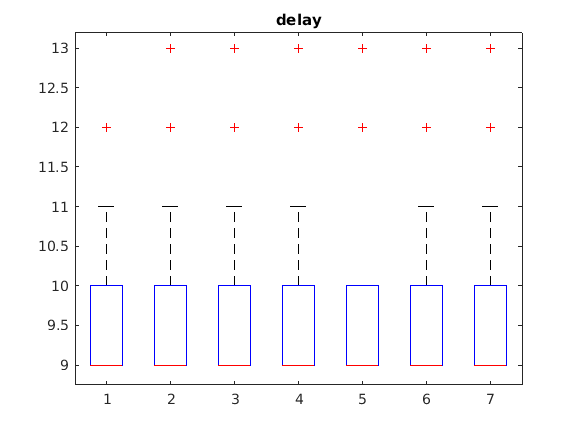

sentFile = ["1_3tab_noSEPA_sent.dat"
    "2_3tab_txSEPA_sent.dat"
    "3_3tab_rxSEPA_sent.dat"
    "4_3tab_tabSEPA_sent.dat"
    "5_3tab_tx-tabSEPA_sent.dat"
    "6_3tab_tx-tab-rxSEPA_sent.dat"
    "7_3tab_3tabSEPA_sent.dat"
    ];

sent_cnt = length(sentFile);

recvFile = ["1_3tab_noSEPA_recv.dat"
    "2_3tab_txSEPA_recv.dat"
    "3_3tab_rxSEPA_recv.dat"
    "4_3tab_tabSEPA_recv.dat"
    "5_3tab_tx-tabSEPA_recv.dat"
    "6_3tab_tx-tab-rxSEPA_recv.dat"
    "7_3tab_3tabSEPA_recv.dat"
    ];
    
recv_cnt = length(recvFile);

for cnt = 1:1:sent_cnt
    sent_data(cnt)= {csvread(sentFile(cnt))};
    recv_data(cnt) = {csvread(recvFile(cnt))};
end

sent_array = cell2mat(sent_data);

recv_array = [];
for cnt = 1:1:recv_cnt
    temp_data =cell2mat(recv_data(cnt));
    temp_data = temp_data(1:970,:);
    recv_array = [recv_array temp_data];
end


nretx = [];
result = [];
delay = [];
diversity = [];
snr= [] ;
rssi = [];

for cnt = 1:1:sent_cnt
    nretx = [nretx sent_array(:,1 + 3*(cnt-1))];
    result = [result sent_array(:,2 + 3*(cnt-1))];
    delay = [delay sent_array(:,3*cnt)];
    
    diversity = [diversity recv_array(:,1 + 3*(cnt -1))];
    snr = [snr recv_array(:,2 + 3*(cnt -1))];
    rssi = [rssi recv_array(:,3*cnt)];
end



boxplot(delay)
title("delay")

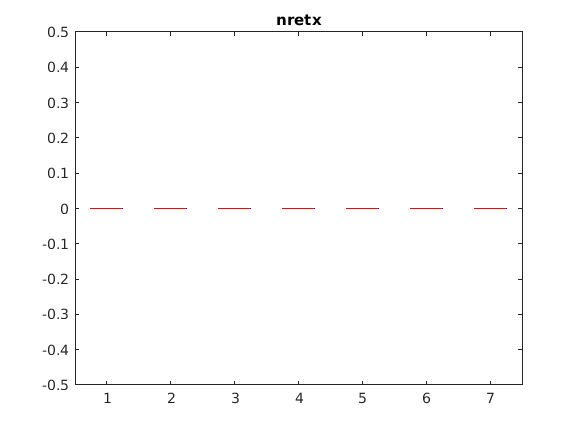

boxplot(nretx)
title("nretx")

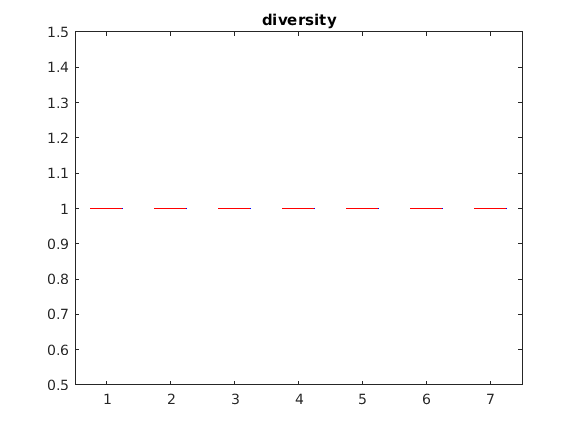

boxplot(diversity)
title("diversity")

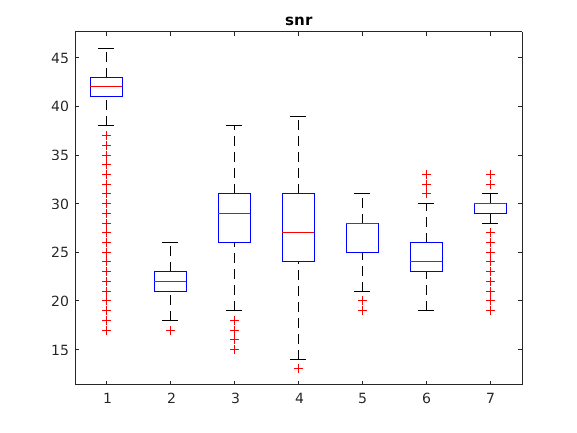

boxplot(snr)
title("snr")

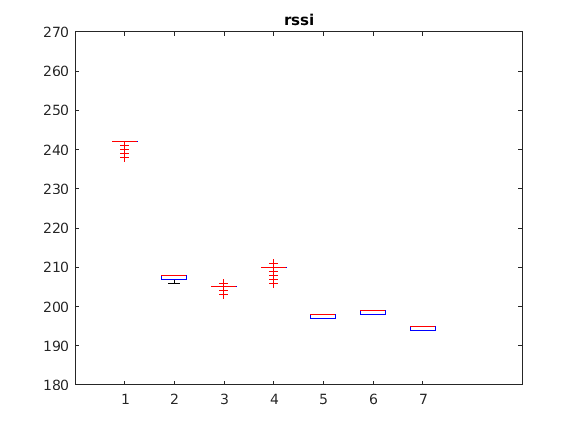

boxplot(rssi)
title("rssi")
axis( [0 9 180 270])